# **InverseJacobiAM**

Inverse Jacobi Amplitude Function

## Definition


$${\textrm{am}}^{-1} \left(x\left|m\right.\right)\equiv F\left(x\left|m\right.\right)$$



$${\mathrm{am}}^{-1} \left(x,k\right)\equiv {\mathrm{am}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parameter, *k *is the modulus, $F\left(x|m\right)$ is  Legendre form of the elliptic integral of the first kind.

Domain:  If $-\infty <m<1$ then $-\infty <x<\infty$ (quasi-periodic). If $m>1$ then $\left|x\right|<{\mathrm{sin}}^{-1} \left(1/\sqrt{m}\right)$.  For the specified domain, the  codomain  is the set of real numbers.

Basic features:

${\mathrm{am}}^{-1} \left(-x\left|m\right.\right)=-{\mathrm{am}}^{-1} \left(x\left|m\right.\right)$   (odd)

${\textrm{am}}^{-1} \left(n\pi \pm x\left|m\right.\right)=2n\;K\left(m\right)\pm {\textrm{am}}^{-1} \left(x\left|m\right.\right)$,  $\left|x\right|<\pi /2,\;\;m<1$   (quasi-periodic)

Special values:

${\textrm{am}}^{-1} \left(x\left|\pm \infty \right.\right)=0$,    ${\textrm{am}}^{-1} \left(0\left|0\right.\right)=0$

${\mathrm{am}}^{-1} \left(0\left|m\right.\right)=0$,   ${\mathrm{am}}^{-1} \left(\frac{\pi }{2}\left|m\right.\right)=K\left(m\right)$

${\mathrm{am}}^{-1} \left(x\left|0\right.\right)=x$,    ${\textrm{am}}^{-1} \left(x\left|1\right.\right)={\mathrm{gd}}^{-1} x$

Identities:


$${\mathrm{am}}^{-1} \left(\mathrm{am}\left(x\left|m\right.\right)|m\right)=x,\;\;\;\;|x|<\pi /2$$


## Syntax

Y = InverseJacobiAM(X,K)

y = ijam(x,k)

Y = mInverseJacobiAM(X,M)

y = mijam(x,m)

**Note. **InverseJacobiAM is equal to pEllipticF

## Description

**Y = InverseJacobiAM(X,K)** return${\;\textrm{am}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **InverseJacobiAM** is the wrapper function which calls the functions **ijam** element-wise via the function **ufun2**.

**y = ijam(x,k)** return the value of ${\textrm{am}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijam** is the wrapper function which calls the functions **mijam**.

**Y = mInverseJacobiAM(X,M)** returns${\textrm{am}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mInverseJacobiAM** is the wrapper function which calls the functions **mijam** element-wise via the function **ufun2**.

**y = mijam(x,m)** compute value of ${\textrm{am}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijam **call the function **pelmF**  for calculation of ${\mathrm{am}}^{-1} \left(x\left|m\right.\right)$.

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 0.5;
% Maple 0.505088727578648_079
[ijam(x,k), InverseJacobiAM(x,k), mijam(x,k^2), mInverseJacobiAM(x,k^2)]

ans =    0.505088727578648   0.505088727578648   0.505088727578648   0.505088727578648


fprintf('%.16g\n',ijam(0.5,2)) 

ans =    0.505088727578648   0.505088727578648   0.505088727578648   0.505088727578648


0.6774175382039304


%  Maple  0.6774175382039303_85

Special values

m = -2;
x = -0.5;  % |x| <= 1
mijam(0,m)

ans = 0

disp(mijam(pi/2,m) - melK(m))  % m < 1 !!!

     0



mijam(x,-inf)

ans = NaN

disp(mijam(x,0) - x) 

     0



disp(mijam(x,1) - igd(x))  % igd is inverse Gudermann function

     0



mijam(x,inf)  % x = 0

ans = NaN

Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mInverseJacobiAM(-x,m) + mInverseJacobiAM(x,m))

     0



k=0.995;
x = 0.5;
disp(JacobiAM(InverseJacobiAM(x,k),k)-x)

     0



**Vector input**

k = [0.1, 0.5, 0.89, 0.99995];
x=0.7*ones(size(k));
disp(JacobiAM(InverseJacobiAM(x,k),k)-x)

     0     0     0     0



**Matrix input**

k = [0.1, 0.5, 0.89; -0.1, -0.97, 0.99995 ]';
x=0.7*ones(size(k));
disp(JacobiAM(InverseJacobiAM(x,k),k)-x)

     0     0
     0     0
     0     0



## **Plot **

**Example 1**

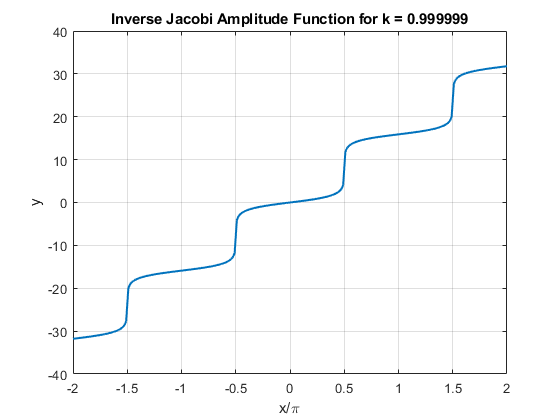

figure
x=-2:0.01:2;
k = 0.999999;
plot(x,InverseJacobiAM(x*pi,k),'LineWidth',1.5)
xlabel('x/\pi')
ylabel('y')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Inverse Jacobi Amplitude Function for k = %g',k))
grid on

**Example 2**

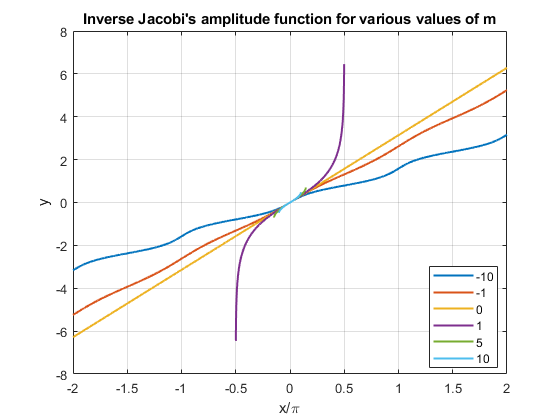

figure
X = -2:0.001:2;
M = [-10,-1,0,1,5,10];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiAM(pi*X,M(i));
end
plot(X,SN,'LineWidth',1.5)
%axis([min(X) max(X) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse Jacobi''s amplitude function for various values of m')
xlabel('x/\pi')
ylabel('y')

**Example 3**

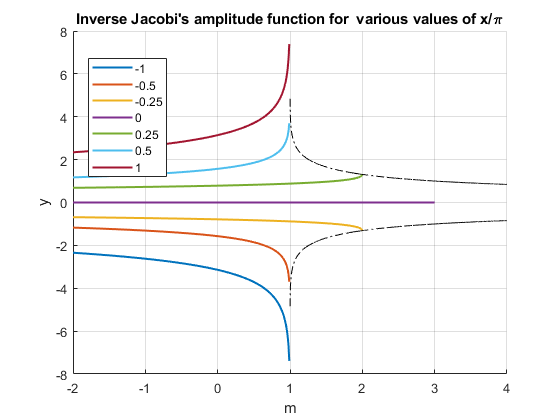

figure
hold on
M = -2:0.01:3;
X = [-1,-0.5,-0.25,0,0.25,0.5,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiAM(pi*X(i),M);
end
plot(M,SN,'LineWidth',1.5)
%axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse Jacobi''s amplitude function for  various values of x/\pi')
xlabel('m')
ylabel('y')
M = 1:0.001:4;
X = asin(1./sqrt(M));
F = mInverseJacobiAM(X,M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
hold off

**Example 4**

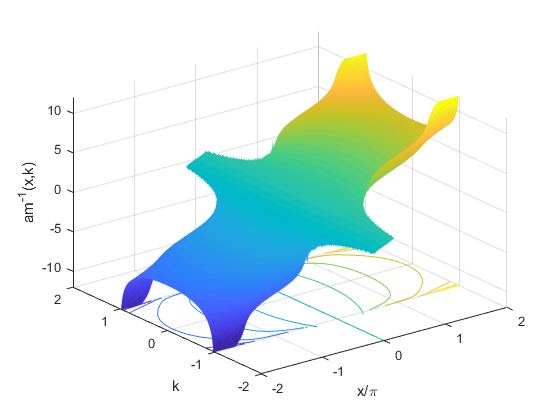

figure
x=-2:0.01:2;
k=-2:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,InverseJacobiAM(pi*X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -12;
hc.LineWidth = 0.5;
hc.LevelList = -12:2:12;
caxis([-12 12])
view(3);
xlabel('x/\pi')
ylabel('k')
zlabel('am^{-1}(x,k)')
zlim([-12 12])
grid on

**Example 5**

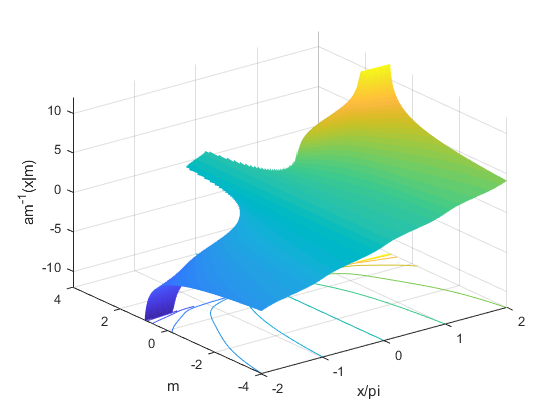

figure
x=-2:0.01:2;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiAM(pi*X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -12;
hc.LineWidth = 0.5;
hc.LevelList = -12:2:12;
view(3)
caxis([-12 12])
xlabel('x/pi')
ylabel('m')
zlabel('am^{-1}(x|m)')
zlim([-12 12])
grid on

**Example 6**

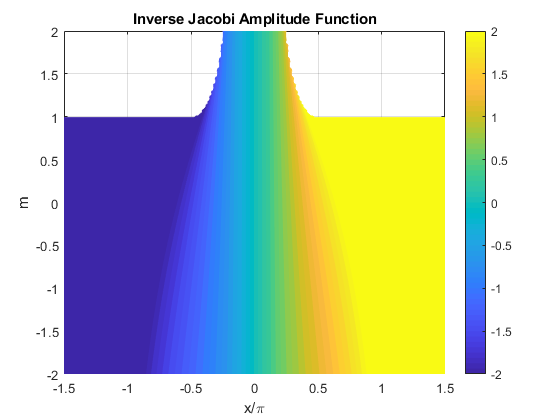

figure
f = @(x,m)mInverseJacobiAM(pi*x,m);
fcontour(f,[-1.5 1.5 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi Amplitude Function')
colorbar
xlabel('x/\pi')
ylabel('m')
grid on

**Example 7**

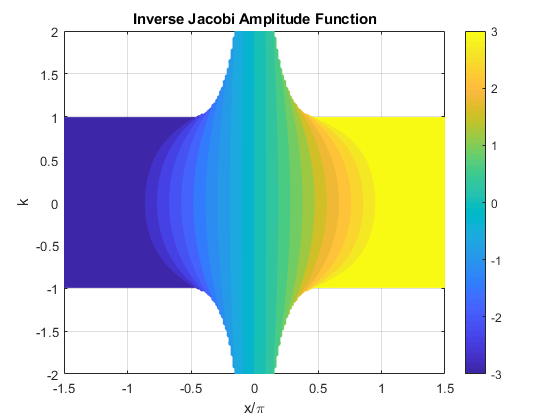

figure
f = @(x,k)InverseJacobiAM(pi*x,k);
fcontour(f,[-1.5 1.5 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi Amplitude Function')
colorbar
xlabel('x/\pi')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

## See Also